# ReadData

For reading data from the Arduino.

You can find the port by going to 'tools -> Port' in the Arduio application. 

For a PC, it will be something like COM6, and for a Mac, it will be something like /dev/cu.usbmodem1451

#### This code automatically finds the port for me :)

allPorts = serialportlist                   % Saves a list of all available ports (string array)

allPorts = 1×6 string array
    "/dev/cu.BLTH"    "/dev/tty.BLTH"    "/dev/cu.Bluetooth-Incoming-Port"    "/dev/tty.Bluetooth-Incoming-Port"    "/dev/cu.usbmodem1413401"    "/dev/tty.usbmodem1413401"


pat = "/dev/cu.usbmodem";                    % text to look for
%pat = "/dev/cu.usbserial"; 
matchingPorts = startsWith(allPorts, pat);   % Creates a logical array indicating matching ports

if any(matchingPorts)               % Checks if any matches were found
    numMatches = sum(matchingPorts); % Counts the number of matches
    if size(numMatches) > 1         % If multiple matching ports were found, throw error
        error("Multiple ports found")
    else
        port = allPorts(matchingPorts)   % If one match was found, save that string as the arduino port
    end
else
    error("Port not found")         % Throw an error otherwise
end

port = "/dev/cu.usbmodem1413401"

s = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(s, "CR/LF")
%s.terminator = newline;
%fopen(s);
%s = serial(port, 'BaudRate', 115200);
%s.terminator = newline;
%fopen(s)

do a read to get Ready! from Arduino

%dummy = fgets(s);
dummy = readline(s)

dummy = "Ready!"

Read data after sending command to Arduino

disp('Starting Counting Event in Arduino')

Starting Counting Event in Arduino


%fprintf(s,'%s\n','S'); % send start signal to Arduino
writeline(s,"S");
k = 0;

Read Data from Arduino

%data = fgets(s);
arduinoData = struct("Time",{},"motorCommand",{},"angVelocity",{});
data = readline(s);
disp(data);          % Display the data

1000	255	0.0000000	0.0000000


clear dataTable
dataarray = strsplit(data,'\t');
while (~strncmp(data,'Finished',8)) % Read data until Arduino signals that it is done
    k = k + 1;
    dataarray = strsplit(data,'\t');     % change string data to cell array using tab delimiter
    %arduinoData = {str2double(dataarray{1}),str2double(dataarray{2}),str2double(dataarray{3})}
    % save data converting strings to numberssave somedata.mat Time Count
    Time(k) = str2double(dataarray{1});
    motorCommand(k) = str2double(dataarray{2});
    angVelocity(k) = str2double(dataarray{3});
    angPosition(k) = str2double(dataarray{4});
    
    %arduinoData(k).Time = Time(k);
    %arduinoData(k).motorCommand = motorCommand(k);
    %arduinoData(k).angVelocity = angVelocity(k);

    data = readline(s);    % Read Data from Arduino
    disp(data);          % Display what you got
end

1005	255	0.3926991	0.0019635
1010	255	1.9634954	0.0117810
1015	255	3.1415927	0.0274889
1020	255	3.9269909	0.0471239
1025	255	4.3196902	0.0687223
1030	255	5.1050882	0.0942478
1036	255	5.4977874	0.1217367
1040	255	5.1050882	0.1472622
1045	255	6.6758852	0.1806416
1050	255	7.4612822	0.2179480
1055	255	7.8539819	0.2572179
1060	255	8.6393804	0.3004148
1065	255	8.6393804	0.3436117
1070	255	9.0320796	0.3887721
1075	255	9.4247789	0.4358960
1080	255	7.8539819	0.4751659
1085	255	10.2101764	0.5262168
1090	255	10.2101764	0.5772677
1095	255	10.2101764	0.6283185
1100	255	10.9955749	0.6832964
1105	255	10.6028757	0.7363109
1110	255	11.3882741	0.7932522
1115	255	10.9955749	0.8482301
1121	255	11.7809734	0.9071350
1125	255	9.0320796	0.9522953
1130	255	11.7809734	1.0112001
1135	255	11.7809734	1.0701050
1140	255	12.1736717	1.1309734
1145	255	11.7809734	1.1898782
1150	255	12.5663709	1.2527101
1155	255	12.1736717	1.3135784
1160	255	12.1736717	1.3744468
1165	255	10.2101764	1.4254977
1170	255	12.1736717	1.48636

clear s;

data

data = "Finished"

Plot results

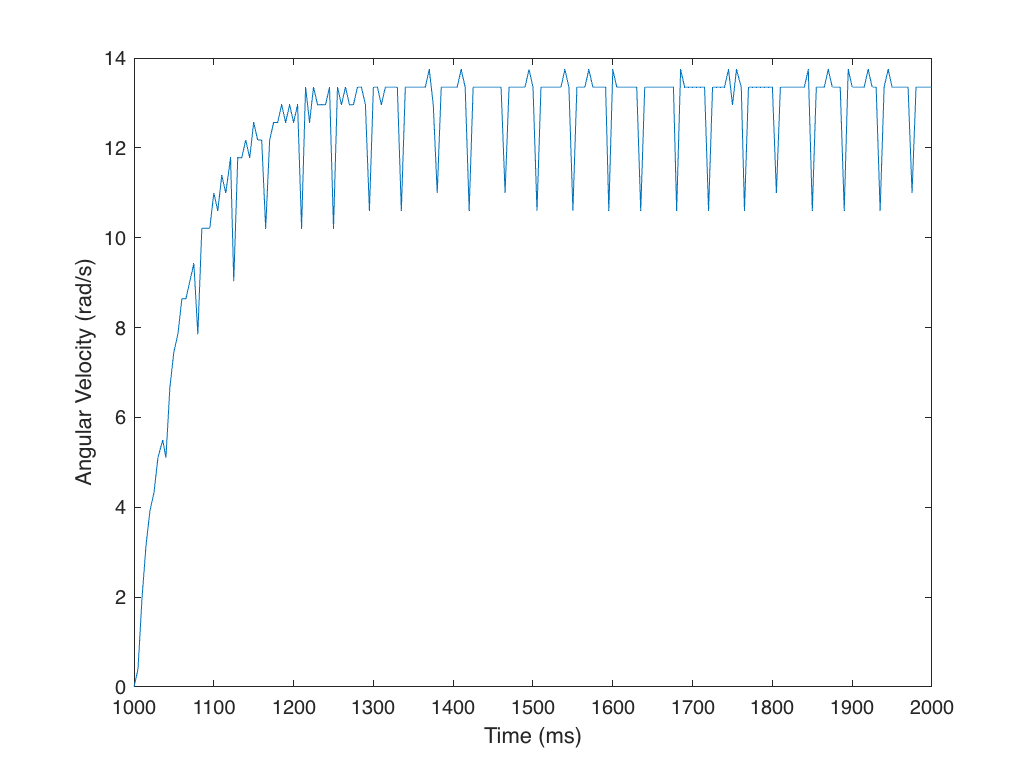

plot(Time,angVelocity)
xlabel('Time (ms)')
ylabel('Angular Velocity (rad/s)')

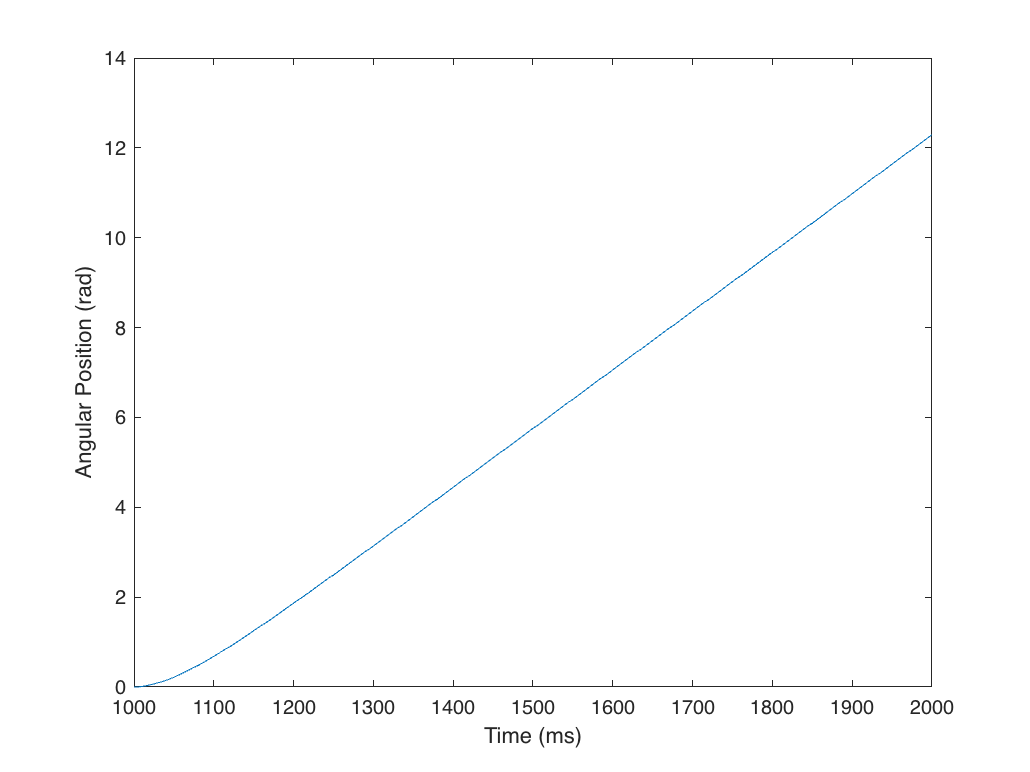


plot(Time,angPosition)
xlabel('Time (ms)')
ylabel('Angular Position (rad)')

Save results in a .mat file to use later

save somedata.mat Time motorCommand angVelocity

I have a crazy idea. Instead of finding a transfer function of Position/Voltage, why not do position/motorCommand?

dataTable = table(Time(:),motorCommand(:),angVelocity(:),angPosition(:),angVelocity(:)/7.2);

dataTable.Properties.VariableNames = ["Time","Speed","Velocity","Position","VelocityNew"];
%pastData = cell2table(pastData);
dataTable.Time = (dataTable.Time -1000)/1000;
dataTable;

Max voltage is Vcc, so 5V. To find the *unit* step response, need to divide the output by 5

%pastData.VelocityNew = pastData.Velocity/5

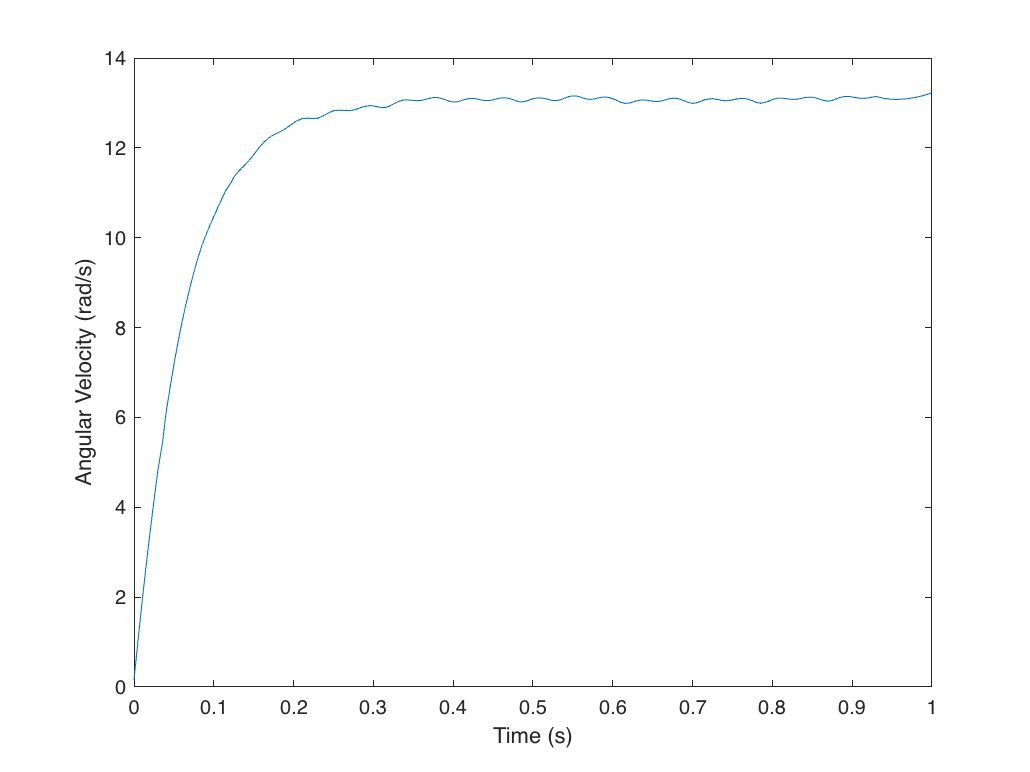

% Smooth input data
newTable = smoothdata(dataTable,"loess","SmoothingFactor",0.55,...
    "DataVariables",["Velocity","VelocityNew"]);
plot(newTable.Time,newTable.Velocity)
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')

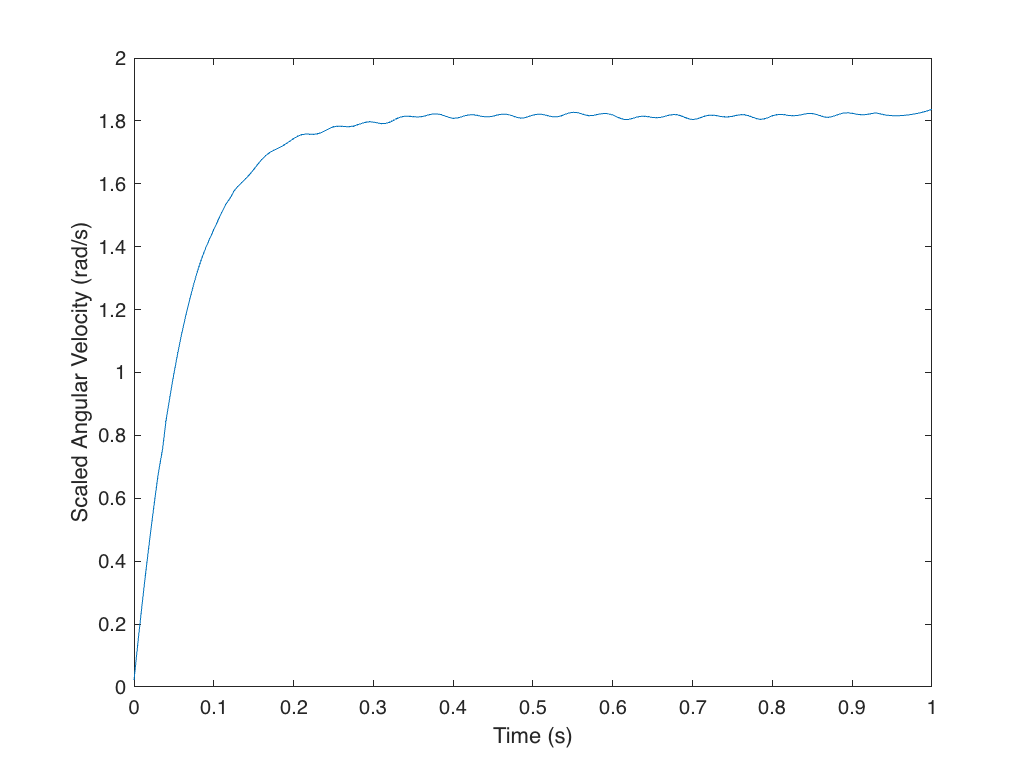


plot(newTable.Time,newTable.VelocityNew)
xlabel('Time (s)')
ylabel('Scaled Angular Velocity (rad/s)')

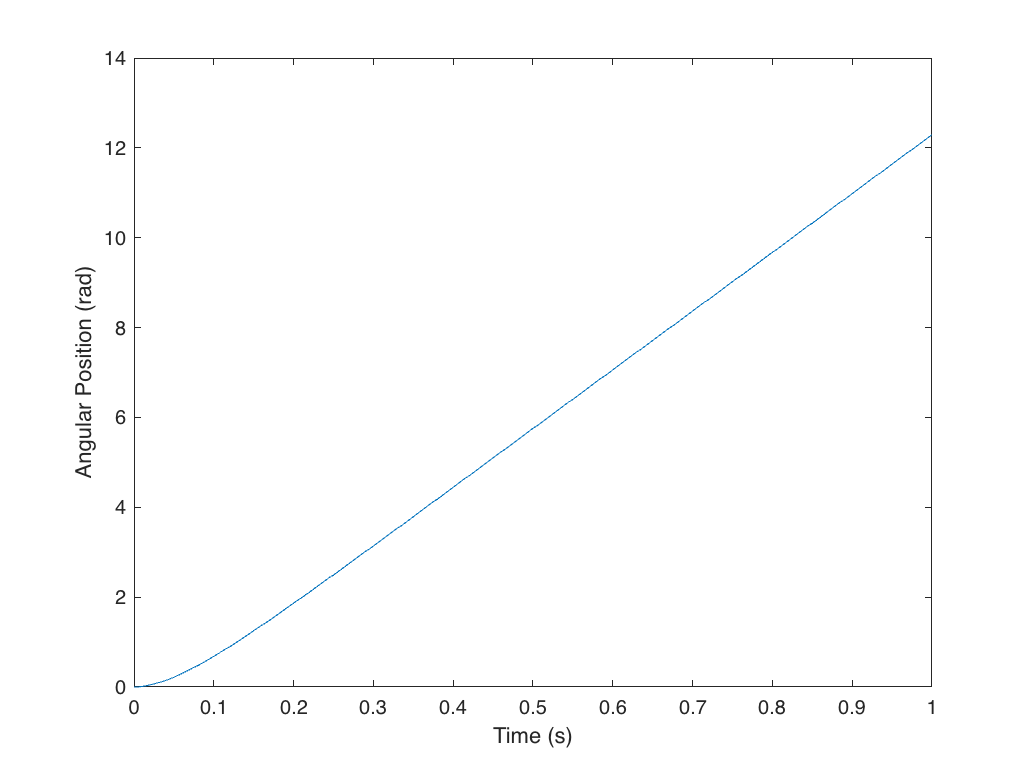


plot(newTable.Time,newTable.Position)
xlabel('Time (s)')
ylabel('Angular Position (rad)')

% plot(newTable.Time,newTable.Position)

Calculate the maximum speed of the motor (K)

K = newTable.VelocityNew(newTable.Time > .400);
K = mean(K)

K = 1.8171

newTable.VelocityNew(newTable.VelocityNew <= 0.64*K+0.1 & newTable.VelocityNew >= 0.64*K-0.1);
sigma = 1./newTable.Time(newTable.VelocityNew <= 0.64*K+0.1 & newTable.VelocityNew >= 0.64*K-0.1)

sigma =    18.1818
   16.6667
   15.3846
   14.2857


sigma = mean(sigma)

sigma = 16.1297

s=tf('s');
velTf = K*(sigma)/(s+sigma)

velTf =
 
    29.24
  ---------
  s + 16.13
 
Continuous-time transfer function.



posTf = velTf*(1/s)

posTf =
 
      29.24
  -------------
  s^2 + 16.13 s
 
Continuous-time transfer function.



Compare motor step with transfer function

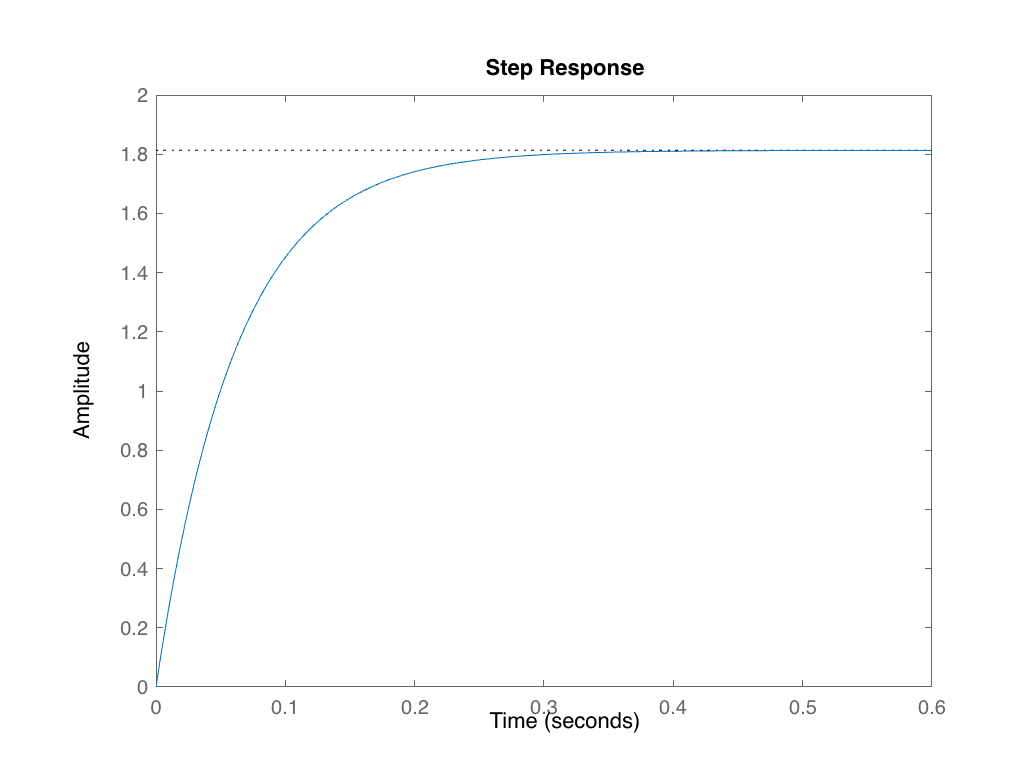

riseTime = 0.1362

settlingTime = 0.2855

overshoot = 0

stepplot(velTf)

Design a PI controller that achieves closed loop step response specifications of a rise time of 1 second and an overshoot of less than or equal to 12%, with zero steady state error.

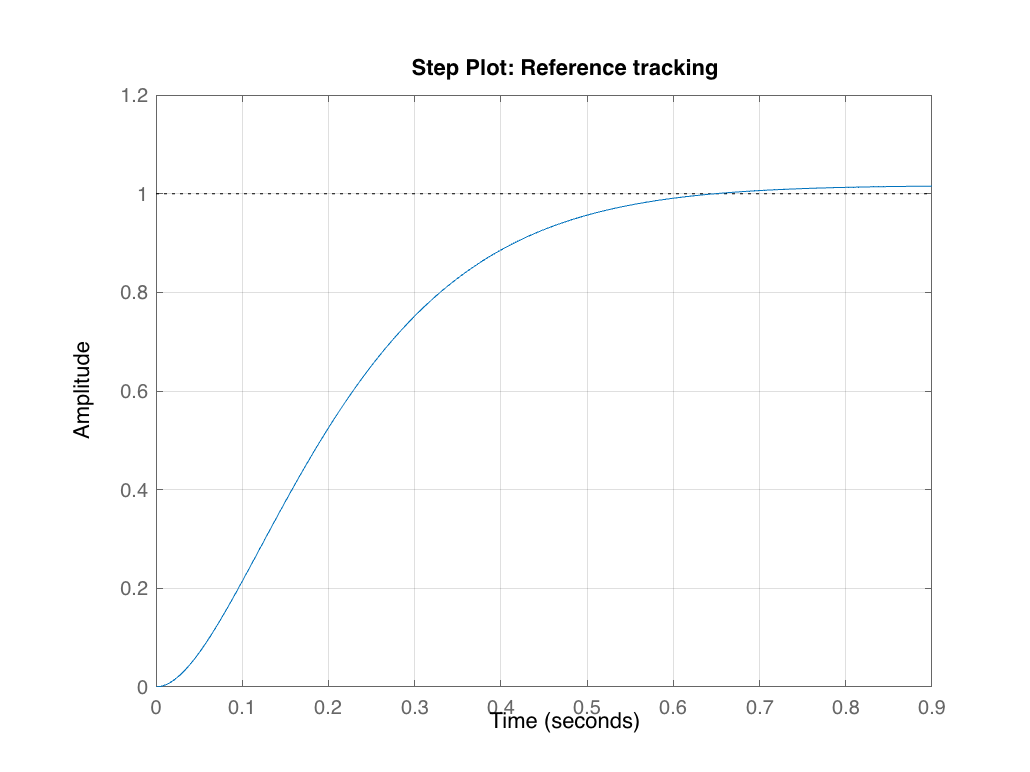

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc2 = 2/0.462545;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM2 = 100*0.9;

% Define options for pidtune command
opts2 = pidtuneOptions('PhaseMargin',PM2);

% PID tuning algorithm for linear plant model
[C,pidInfo] = pidtune(posTf,'PI',wc2,opts2);

% Clear Temporary Variables
clear wc2 PM2 opts2

% Get desired loop response
Response = getPIDLoopResponse(C,posTf,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 0.3534
    TransientTime: 0.5598
     SettlingTime: 0.5598
      SettlingMin: 0.9030
      SettlingMax: 1.0163
        Overshoot: 1.6276
       Undershoot: 0
             Peak: 1.0163
         PeakTime: 1.1016




% Clear Temporary Variables
clear Response
C.Kp

ans = 2.4688

C.Ki

ans = 0.1868